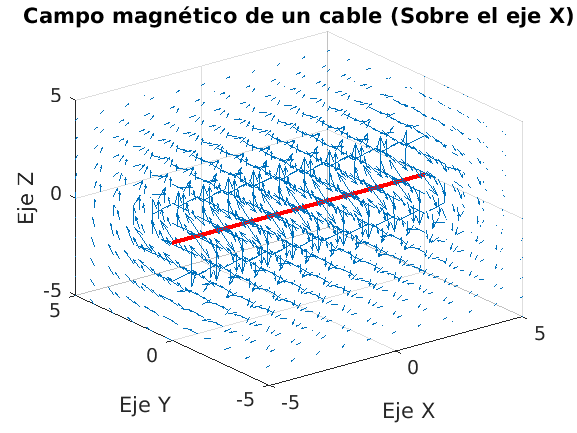

clc
close all
clear


Nx=11;
Nz=11;  
Ny=11;  
N=50;   % length of the wire 


Xw=(floor(-N/2):floor(N/2)); % X-coordinates of the wire
Yw=zeros(N+1,1); % Y-coordinates of the wire
Zw=zeros(N+1,1); % Z-coordinates of the wire

I=3;    % current 
u0=1;   % permeability

xp(1:Nx)=-(Nx-1)/2:(Nx-1)/2;  
yp(1:Ny)=-(Ny-1)/2:(Ny-1)/2;    
zp(1:Nz)=-(Nz-1)/2:(Nz-1)/2;  

X(1:Nx,1:Ny,1:Nz)=0;
Y(1:Nx,1:Ny,1:Nz)=0; 
Z(1:Nx,1:Ny,1:Nz)=0;

for i=1:Nx
    X(i,:,:)=xp(i); 
end
for i=1:Ny
    Y(:,i,:)=yp(i); 
end
for i=1:Nz
    Z(:,:,i)=zp(i);
end

%-------------------------------------------------------------------------
%------------------------------------------------------------------------


for a=1:Nx  
for b=1:Ny  
for c=1:Nz
    
%-------------------------------------------------------------------------    
%-------------------------------------------------------------------------

for i=1:N-1
Rx(i)=(X(a,b,c)-(0.5*(Xw(i)+Xw(i+1))));
Ry(i)=(Y(a,b,c)-(0.5*(Yw(i)+Yw(i+1))));
Rz(i)=(Z(a,b,c)-(0.5*(Zw(i)+Zw(i+1))));
dlx(i)=Xw(i+1)-Xw(i);
dly(i)=Yw(i+1)-Yw(i);
dlz(i)=Zw(i+1)-Zw(i);
end
Rx(N)=(X(a,b,c)-0.5*(Xw(N)+1));
Ry(N)=(Y(a,b,c)-(0.5*(Yw(N)+1)));
Rz(N)=(Z(a,b,c)-(0.5*(Zw(N)+1)));
dlx(N)=-Xw(N)+1;
dly(N)=-Yw(N)+1;
dlz(N)=-Zw(N)+1;
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------

for i=1:N
Xcross(i)=(dly(i).*Rz(i))-(dlz(i).*Ry(i));
Ycross(i)=(dlz(i).*Rx(i))-(dlx(i).*Rz(i));
Zcross(i)=(dlx(i).*Ry(i))-(dly(i).*Rx(i));
R(i)=sqrt(Rx(i).^2+Ry(i).^2+Rz(i).^2);
end

%-------------------------------------------------------------------------
%--------------------------------------------------------------------------

Bx1=(I*u0./(4*(R.^3))).*Xcross;
By1=(I*u0./(4*(R.^3))).*Ycross;
Bz1=(I*u0./(4*(R.^3))).*Zcross;
%--------------------------------------------------------------------------
%-------------------------------------------------------------------------

BX(a,b,c)=0;       % Initialize sum magnetic field to be zero first
BY(a,b,c)=0;
BZ(a,b,c)=0;

%--------------------------------------------------------------------------
%--------------------------------------------------------------------------

for i=1:N   % loop over all current elements along coil    
    BX(a,b,c)=BX(a,b,c)+Bx1(i);
    BY(a,b,c)=BY(a,b,c)+By1(i);
    BZ(a,b,c)=BZ(a,b,c)+Bz1(i);
end

%-------------------------------------------------------------------------

end
end

end

%--------------visualizing the result-------------------------------------

figure(1)

quiver3(X,Y,Z,BX,BY,BZ,2);
hold on
line([-5 5],[0 0], [0 0],'linewidth',3,'color','r');
axis([-5 5 -5 5 -5 5])
xlabel('Eje X','fontsize',14)
ylabel('Eje Y','fontsize',14)
zlabel('Eje Z','fontsize',14)
title('Campo magnético de un cable (Sobre el eje X)','fontsize',14)
h=gca; 
set(h,'FontSize',14)

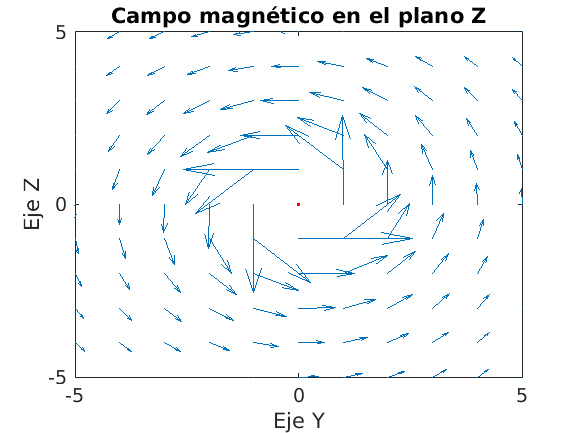

fh = figure(1); 
set(fh, 'color', 'white'); 

figure(2)

quiver(Y((Nx-1)/2,:,:),Z((Nx-1)/2,:,:),BY((Nx-1)/2,:,:),BZ((Nx-1)/2,:,:),2);
hold on
G1=plot(0,0,'.','markersize',6);
set(G1,'MarkerEdgeColor','r')
axis([ -5 5 -5 5])
xlabel('Eje Y','fontsize',14)
ylabel('Eje Z','fontsize',14)
title('Campo magnético en el plano Z','fontsize',14)
h=gca; 
set(h,'FontSize',14)

h = get(gca, 'ylabel');
fh = figure(2); 
set(fh, 'color', 'white');